# 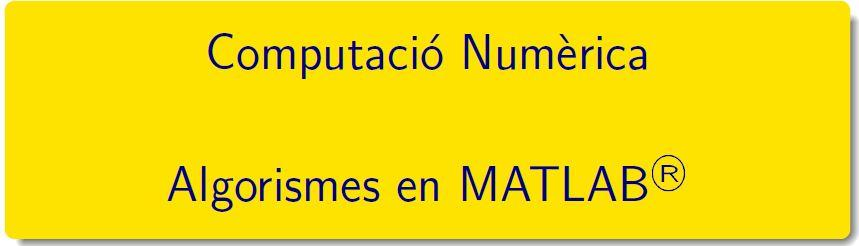

===========================================================================

# PRÀCTICA 2 - Exercici 2

## Algorismes

### Propagació d'errors, com s'evita?

Per tal de reduir o evitar la propagació dels errors es recomana, minimitzar el nombre d’operacions, reordenar les operacions i replantejar el problema en altres termes.

#### Equació de segon grau

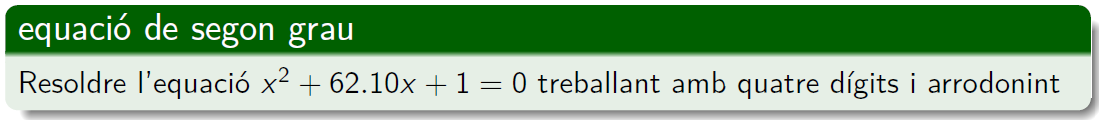

clearvars, format, n=4;
fprintf('fent ús de roots'), arrels =roots([1,62.10 1])

fent ús de roots

arrels =   -62.0839
   -0.0161


Es calcula amb la fórmula $\frac{-b\pm\sqrt{b^2-4ac}}{2a}=-31.05\pm\sqrt{31.05^2-1}$

x1 = -31.05 + sqrt(31.05^2-1);
x2 = -31.05 - sqrt(31.05^2-1);
rformula = [x1 x2];
rformula

rformula =    -0.0161  -62.0839


Es calcula amb la fórmula $x_1=-31.05-\sqrt{31.05^2-1},\quad  x_3 = 1/x_1$

x1 = -31.05 - sqrt(31.05^2-1);
x2 = 1 / x1;
rformula2 = [x1 x2];
rformula2

rformula2 =   -62.0839   -0.0161


Xifres decimales correctes

decimals_correctes = @(x)fix(-log10(2*x)); 
error_absolut = @(x, y) abs(x - y);
xifres_significatives = @(x)fix(-log10(2*x));  
error_relatiu = @(e, x)e/abs(x);


decimals_correctes(error_absolut(arrels(1), rformula(2)))

ans = Inf

xifres_significatives(error_relatiu( error_absolut(arrels(1), rformula(2)), arrels(1)))

ans = Inf

#### Regla de Horner

Per avaluar expressions polinomials 

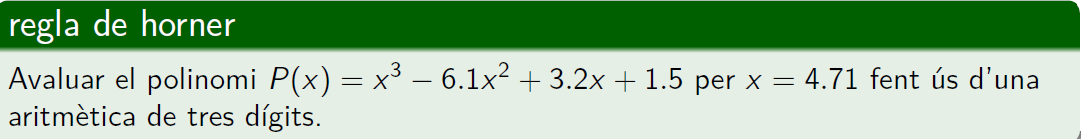

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$

% Per fer
format long
x=4.71; xa=round(x,n,'significant');
a3 = x^3 - (6.1*x^2) + (3.2*x)+ 1.5 %valor exacte

a3 =  -14.263899000000011


coef = [1 -6.1 3.2 1.5];
h = horner(coef, x) %valor horner

h =  -14.263898999999990


- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$fent ús d'una aritmètica aritmética de tres dígits

% Per fer

- Xifres significatives

xifres_significatives(error_relatiu( error_absolut(a3, h), h))

ans =     14


function [ pa ] = horner(coeff,a)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner
pa = coeff(1);
x=a;
for k=2:length(coeff)
    pa = pa.*x + coeff(k);
end
return
end

`Document preparat per M. Àngela Grau Gotés, 24 de febrer de 2022`